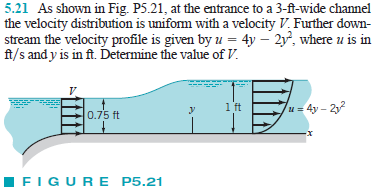

# constants

u = symunit;
rho = 1.94*u.slug/u.ft^3;
w = 3*u.ft;

# inflow properties

syms V1;
h1 = 0.75*u.ft;
A1 = w*h1;
mdot1(V1) = rho*A1*V1;

# outflow properties

syms y;
h2 = 1*u.ft;
V2(y) = 4/u.s*y-2/(u.ft*u.s)*y^2;
mdot2 = int(rho*V2*w, [0 h2]);

# conservation of mass

V1 = solve(mdot1 == mdot2);
V1_vpa = vpa(V1, 3) %#ok

$$V1\_vpa = 1.78\,\frac{\mathrm{ft}}{s}$$

clear V1_vpa;